# Part 3: Cell counting 

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

Microscopy is widely used in biology, so let's look at a microscope image next! Imagine you collected a sample of a patient's blood, and you need to count the number of cells so you can figure out if the cell count is too low, too high, or just right (checking if there are too many, too few, or oddly shaped blood cells in a sample can tell us a lot about what might be going on in a patient's body). As discussed in the introduction, it's inefficient to count such cells on a slide by hand, but the process can be easily automated by importing and segmenting an image of the cells in MATLAB®. 

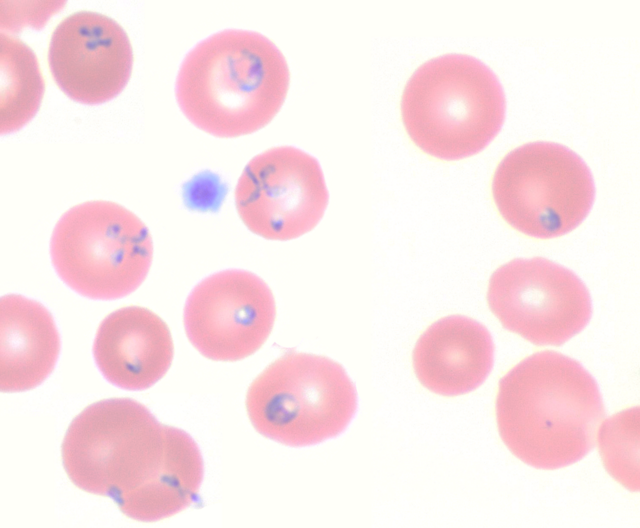

Example of a blood smear that contains [*Babesia microti*](https://commons.wikimedia.org/wiki/File:Blood_smear_of_Babesia_microti,_original.png), a blood-born parasite that can be passed by deer ticks.

## 1: Segment an image by identifying circles 

When you think about the shape of cells, you probably think about circles. In this section, we are going to segment images by shape (circles!). We will start with a simple image of something very circular (coins) before we move to identify cells. 

Load the image 'coins.png' (this image ships with MATLAB, so it will be automatically available and in your path) image using `imread()`: 

coins = imread("coins.png");

### Method 1: Use an app

Under the **Apps** tab, go to 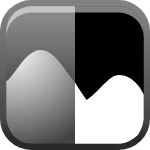** Image Segmenter**. Select 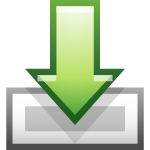** Load Image** and then load coins from the Workspace.

Select 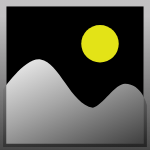 **Find Circles in the top toolbar**

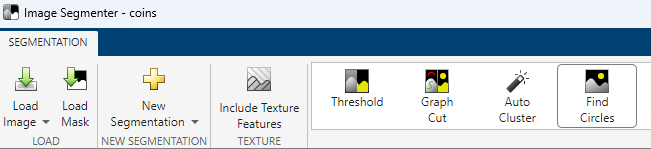

Use the **Ruler** tool in the top left corner to measure the coins and determine the diameter *range* of the circles in the image you want to select.

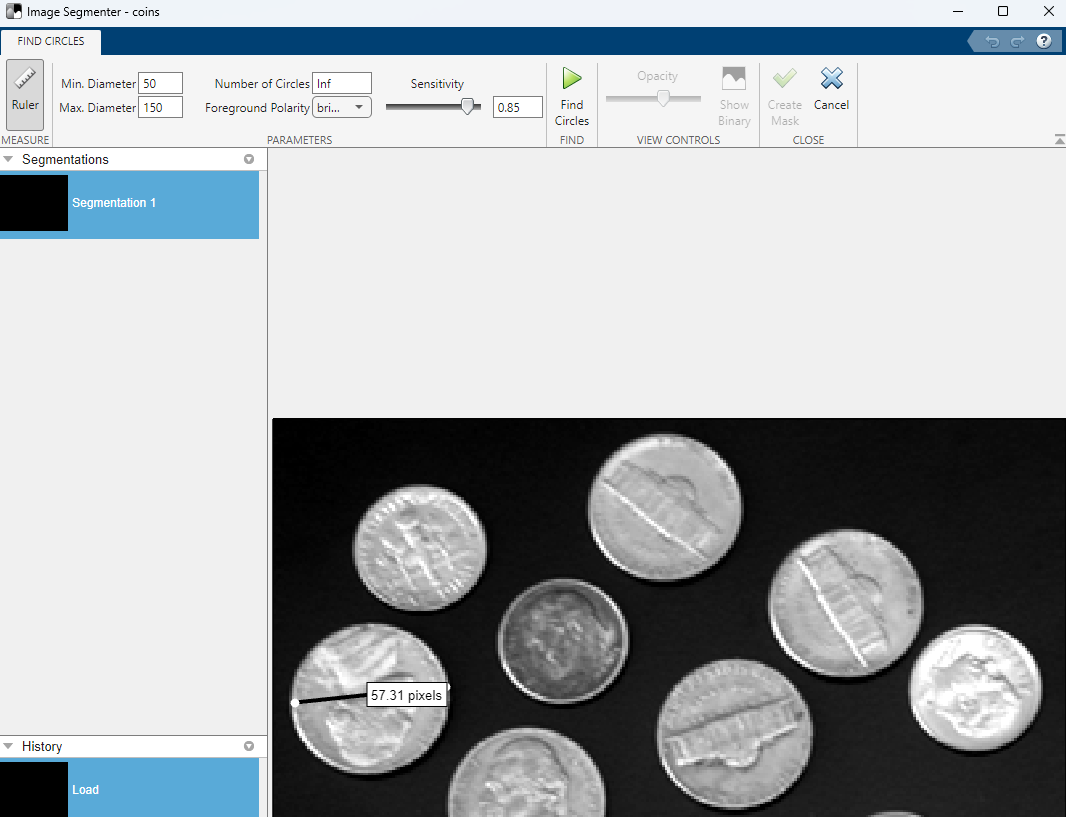

 What do you think is the minimum coin diameter? Maximum? 

We will select our circle detection range to go from a little less than the minimum diameter to a little more than the maximum diameter so that all circles are identified.

In this case, let's use **40 to 70 pixels **as a diameter range. Enter these diameters. In this case, you don't need to change the Foreground Polarity or Sensitivity but note that those are options that we will explore later in an example of an actual biological image. 

Then select 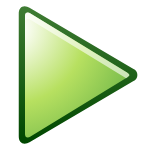**Find Circles**. Your circles will be highlighted. 

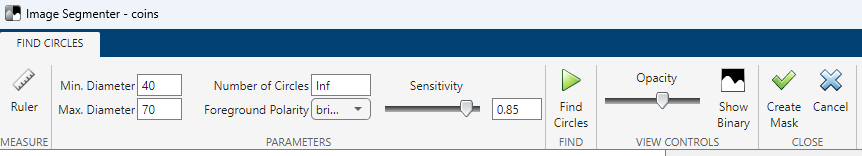

  Challenge: Now that you've found the circles in the image, select 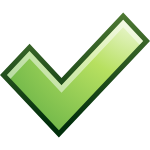**Create Mask** and then **Export**. As we did in [section 2](matlab: edit S2_Plant_img_segmentation.mlx), load the mask (`BW`) into the 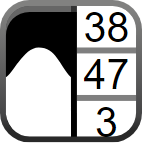 **Image Region Analyzer** app. Click **Export** and then **Export properties. **

Just as before, we have the table `propsTable` in our Workspace, which has several different variables describing our coins. Type `propsTable.EquivDiameter` to see the diameter of each coin: 

See if you can use a different `propsTable` variable to find the area of the coins. 

Close the Image Region Analyzer and Image Segmenter when you complete this section. 

### Method 2: Find circles programmatically

To include the entire workflow, let's start by loading our image (even though we already did that above).

#### 1: Load image

coins = imread("coins.png");

#### 2: Display image

  Use` imshow() `to display `coins`: 

#### 3: Determine the radius of typical cells

The programmatic method we are going to use will find circles based on a given range of radii. In the app, we used diameter and our range was 40 to 70 pixels. If we want the radius, we would divide this range in half, and use **20-35 pixels**. 

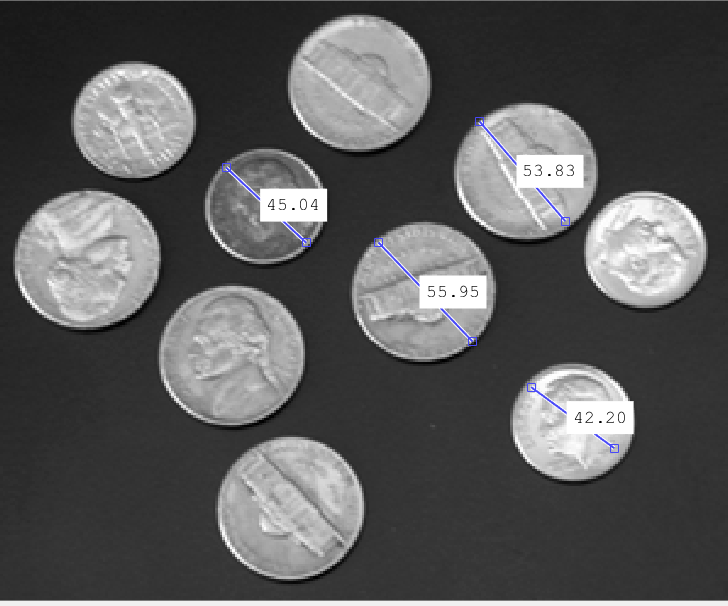

#### 4: Segment the image by finding the circles 

We use the [Hough transform](https://www.mathworks.com/help/images/ref/hough.html) to extract features of certain shapes from an image. The image processing toolbox has a function [`imfindcircles()`](https://www.mathworks.com/help/images/ref/imfindcircles.html) which uses a circular Hough transform to find circles with a specific radius or within a specific range of radii. 

Run: 

[centers, radii] = imfindcircles(coins,[20 35])

The first input to `imfindcircles` is the image to segment, and the second is the range of radii. There are two outputs: `centers` is a matrix that lists the x and y coordinates of the center of each circle, and `radii` is an array of the radii of each circle.

One quick and dirty way to see how many cells you identified is to just count how many radii you found. [`length()`](https://www.mathworks.com/help/matlab/ref/length.html) will tell us how many values are in our array. So if we take `length(radii)`, we will know how many radii, and therefore how many circles, were detected. 

  Type `length(radii)`in the code block and run the cell: 

 How many coins were detected? Does that match up with what you expected? 

  Try changing the radius range around and see how the number of coins that you identify changes! 

#### 6: Visualize detected circles 

You can also draw the identified circles on the image to visually check that the identification is working using the function [`viscircles()`](https://www.mathworks.com/help/images/ref/viscircles.html). Note that this function uses the most recently opened image or plot (the current axes) and draws the circles on it (in this case, we ran `imshow(coins)` in step 2, and that is our most recently opened image). 

viscircles(centers,radii) 

It looks like all coins were identified here! [`viscircles()`](https://www.mathworks.com/help/images/ref/viscircles.html) draws perimeters of circles with a certain (x,y) center location and a specified radius. 

For fun, you can try changing the properties of the circle visualization, like the color. 

  Try typing 

into the code block. 

Play around with the color input (currently "g") to modify the edge color. 

Now for the fun part: try it yourself with a real biological image! 

## 2:  Exercise- identify and count cells! 

Let's load and examine an image of blood cells. A blood smear is a diagnostic test that a doctor might use to count blood cells and platelets. Both the shapes of the cells and the number of the cells are really important. For example, an abnormally high number of white blood cells in a sample would indicate that some kind of infection is present and the immune system is sending excess white blood cells to fight it! A low red blood cell count might point to a disease such as anemia. Blood is taken from a patient and then a drop is placed on a slide, which is viewed under a microscope! Let's look at one example image of a slide here, and count the number of blood cells. 

#### 1: Load image 

addpath("images")
cells = imread("Tbrucei_thin_wrgiemsa5.jpg");

#### 2: Display image 

Use `imshow()` to display `cells`. 

So we have a color image of cells loaded. Let's say we want MATLAB to automatically detect these purple cells.  

#### 3: Estimate radius range of cells

First, we'll determine the appropriate radius range to use to identify the circles in this image. 

Use` imtool()` to pull up the image and use the ruler tool to measure the radius of cells. 

 Consider and jot down what you think an appropriate radius range might be. 

#### 4: Find circles using the estimated radius range 

Use` imfindcircles() `and the radius range you chose in (3) to try to find circles. Remember to output both the radius and center position of each circle. 

 At this point, you are probably not finding any circles at all in your image (don't worry, this is the 'correct answer' for this section)! Consider why this might be. What is different about this blood smear image and the image of the coins we used before? If you want, go to the [`imfindcircles()` documentation](https://www.mathworks.com/help/images/ref/imfindcircles.html) and try to figure out why the code might be failing to identify these coins. Once you've finished brainstorming, proceed to the next task.

#### 5: Understand why we aren't finding circles 

Despite measuring the circles in the image, we noted above that the circles are not detected. 

This is because the default setting of [`imfindcircles()`](https://www.mathworks.com/help/images/ref/imfindcircles.html) is to find circles that are brighter than the background. In the coins image, the coins are brighter than the dark background and are therefore detected. You can change the polarity of objects that you want `imfindcircles` to look for. Let's try changing the  `"objectPolarity"` option in `imfindcircles` to `"dark"` so that the function identifies circles that are darker than the background. 

[centers, radii] = imfindcircles(cells,[10 25],"ObjectPolarity", "dark")

This time, circles are being identified! :) 

#### 6: Visualize identified circles 

First, open up `cells` using `imshow()`:

Then, use `viscircles()` to plot the circles on the image: 

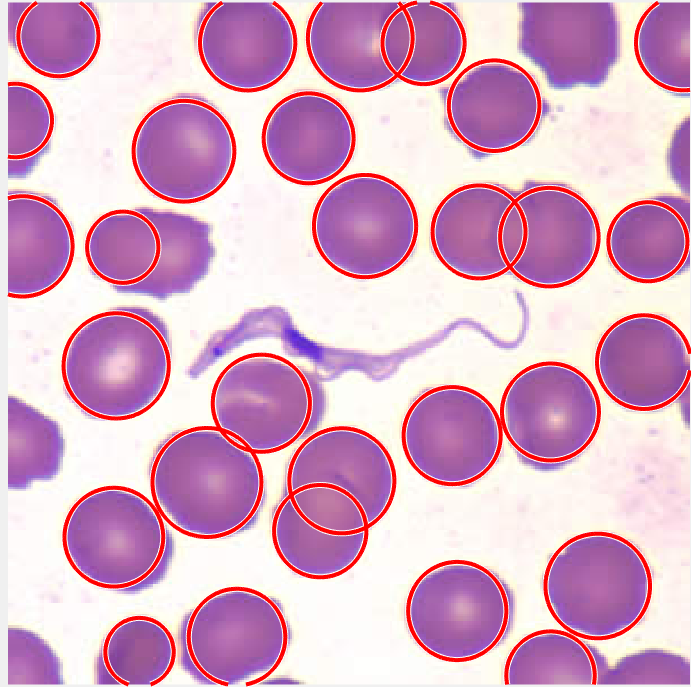

We can see by eye that counting these circles will give a pretty good estimate of the number of cells in the image. 

**Note:** if it looks like your circle detection is very off and maybe you're detecting way too few or way too many cells, you may need to change your radius range a bit. I used [10 25] as the range to produce the image above. 

#### 7: Count cells 

How many cells did you detect? Use `length()` to count the number of cells you found (hint: count the number of radii). 

#### 8: Improving cell detection 

One last thing to consider here! We can see that there are a few cells in the image that we can see by eye but that we didn't detect with `imfindcircles()`. This is probably because these cells are less "circular" than others (slightly odd in shape in some way). One way to adjust how many circles you detect is to play with the sensitivity of the transform. The sensitivity factor can range from 0 to 1, and the default is 0.85. As you go higher in sensitivity, you will become more and more permissive in terms of how many circles you detect. 

First, we will find new circles using a sensitivity of 0.9, which is just slightly higher than the default. 

[centersnew, radiinew] = imfindcircles(cells,[10 25],"ObjectPolarity","dark", "Sensitivity", 0.9);

And then we will visualize them: 

imshow(cells)
viscircles(centersnew, radiinew, "EdgeColor","g");

If we plot the circles we detected using the 0.85 sensitivity on the same image, we can visualize where we detected cells that we hadn't detected before. 

Type `viscircles(centers,radii)` and run the section: 

 What do you notice? Which sensitivity do you think is better? 

You might notice that using a sensitivity of 0.9 gives us a few more cells that we might be interested to find. However, in a couple of instances, it also detects one cell as two cells. 

  Try adjusting the sensitivity to a value between 0.85 and 0.9 to see if you can rectify this. What happens if you make the sensitivity 1?

There's always a trade-off when we're writing some kind of algorithm, such as this simple cell detection algorithm. You want to detect as many cells as possible without labeling 'cells' that aren't cells at all (we would call this 'false alarms'), or double labeling cells! Figuring out where this threshold is for your particular data usually just requires a little bit of trial and error. 

 This blood smear contains a parasite known as [Trypanosoma brucei spp](https://www.cdc.gov/dpdx/trypanosomiasisafrican/index.html).,  which causes a disease commonly known as sleeping sickness and is transmitted to humans by infected tsetse flies. Blood smears such as this one can be used to diagnose this disease. The elongated 'squiggle' in the middle of this image is the parasite. The image is also stained with Wright-Giemsa which is a stain that helps to visualize the cells under the microscope (and is the reason why these cells and the parasite are colored bright purple!). The dark coloring of the parasite aids in diagnosis [1]. 

#### Answers/Sample Code: 

imshow(cells) % 2: Display image 
imtool(cells) % 3: Radius range, this pulls up image viewer 
[centers, radii] = imfindcircles(cells,[10 25]); % 4: find circles
imshow(cells); viscircles(centers, radii) % 6: Visualize circles on image
length(radii)   % 7: count number of circles detected 

## References 

[1] Centers for Disease Control and Prevention. (2019).Trypanosomiasis, African. Retrieved from [https://www.cdc.gov/dpdx/trypanosomiasisafrican/index.html](https://www.cdc.gov/dpdx/trypanosomiasisafrican/index.html)

In this module, we have explored how MATLAB can help us process and make sense of biological images. We've learned how to import, process, display, and segment images. Segmenting images can help us break down an image into items that are meaningful and that we can analyze! In this example, segmenting an image by shape allowed us to quickly identify and count cells. Complete the problem set to practice with a different cell image, and for more information and practice with general image processing, check out the [Image Processing Onramp](https://matlabacademy.mathworks.com/details/image-processing-onramp/imageprocessing). 

[Go to next section (Problem set)](matlab: edit S4_Problem_set.mlx)

[Back to introduction](matlab: edit S1_Introduction.mlx)